向险恶的24题样条插值低头

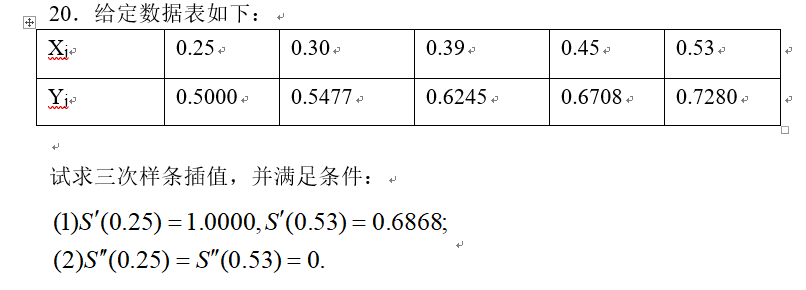

我们来围观一下答案的长度

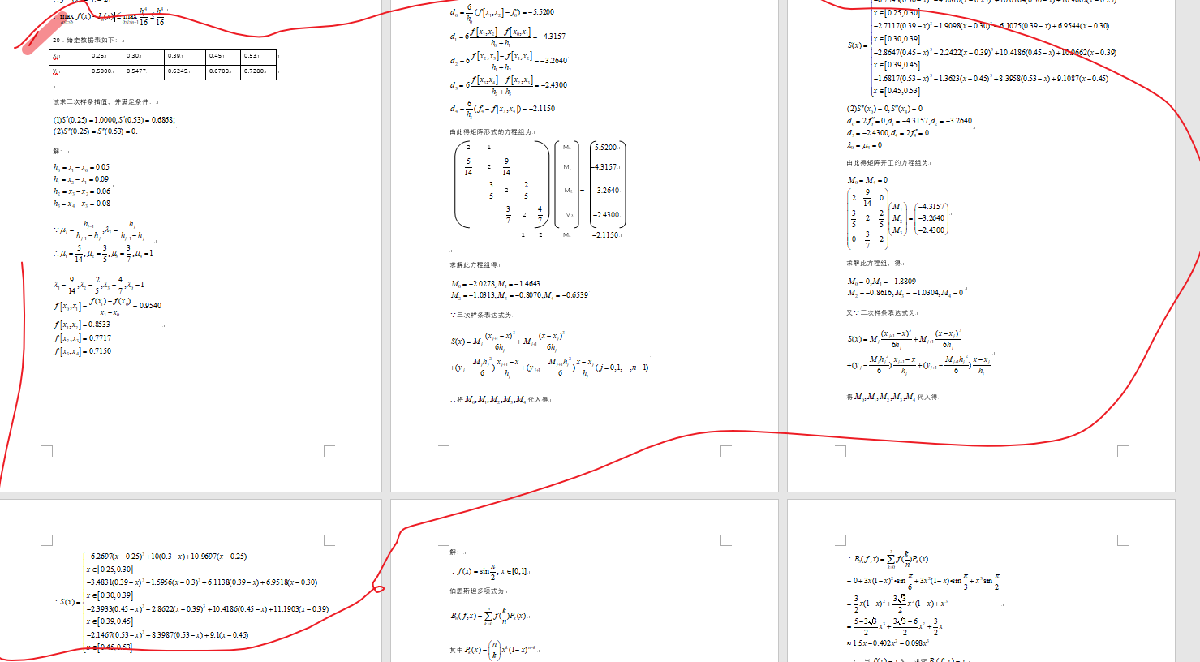

别慌,也就4页

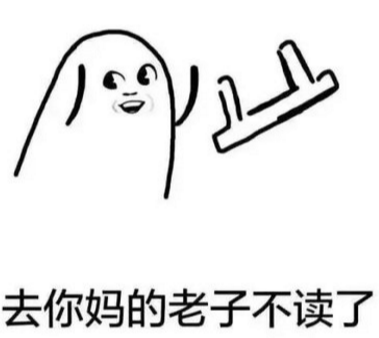

现在我们来介绍一下如何用matlab的spline函数脱离苦海

函数用法参考[https://ww2.mathworks.cn/help/matlab/ref/spline.html](https://ww2.mathworks.cn/help/matlab/ref/spline.html)

clc,clear;

养成好习惯,全部清光光

## 第一小问

不管三七98k我们先把插值点对准备好

x=[0.25 0.3 0.39 0.45 0.53]

x =     0.2500    0.3000    0.3900    0.4500    0.5300


y=[0.5 0.5417 0.6245 0.6708 0.7280]

y =     0.5000    0.5417    0.6245    0.6708    0.7280


计算插值函数,注意因为第一问有两端点初始导数边界条件,所以用[1 y 0.6868]来表示两个端点导数分别为1和0.6868

Q1_struct=spline(x,[1 y 0.6868])

Q1_struct = 包含以下字段的 struct :
      form: 'pp'
    breaks: [0.2500 0.3000 0.3900 0.4500 0.5300]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1


并且返回一个结构体Q1_struct,其用法如下:

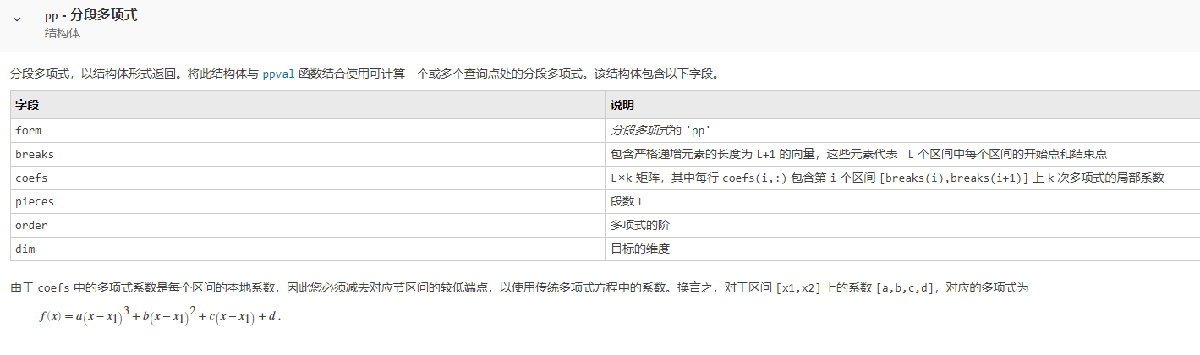

验证插值误差

ppval(Q1_struct,x)

ans =     0.5000    0.5417    0.6245    0.6708    0.7280


打印多项式

Q1_struct.coefs

ans =    61.3334   -6.3867    1.0000    0.5000
  -19.0784    2.8133    0.8213    0.5417
   13.2788   -2.3378    0.8641    0.6245
   -2.5304    0.0524    0.7270    0.6708


注意这个系数指的是(x-xi)^n的多项式系数。换言之，对于区间 `[x1,x2]` 上的系数 `[a,b,c,d]`，对应的多项式为


$$f(x)=a(x-x_1)^3+b(x-x_1)^2+c(x-x_1)+d$$


画个图观察一波

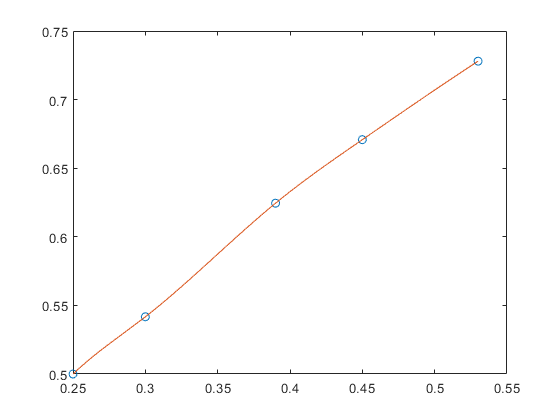

xx = linspace(x(1),x(5),101);
plot(x,y,'o',xx,ppval(Q1_struct,xx),'-');

## 第二小问

计算插值函数,注意因为第2问有两端点初始二阶导数导数边界条件,需要用更强的函数来操作,函数调用方法可以查询doc csape

发现可以设定conds来约束导数结果

conds='second',[0 0];

conds = 'second'

Q2_struct=csape(x,y,conds)

Q2_struct = 包含以下字段的 struct :
      form: 'pp'
    breaks: [0.2500 0.3000 0.3900 0.4500 0.5300]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1


Q2_struct.coefs

ans =    10.2217    0.0000    0.8084    0.5000
  -12.7286    1.5333    0.8851    0.5417
    9.4678   -1.9035    0.8518    0.6245
    0.8302   -0.1993    0.7256    0.6708


ppval(Q2_struct,x)

ans =     0.5000    0.5417    0.6245    0.6708    0.7280


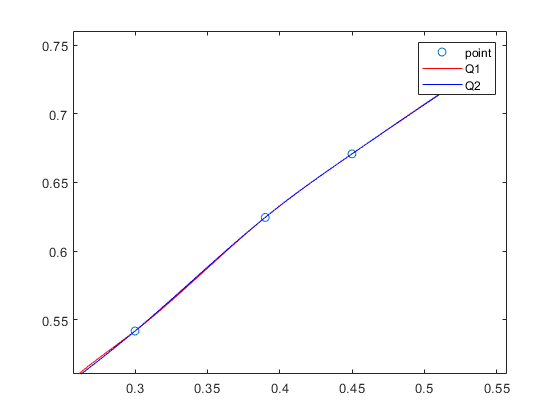

plot(x,y,'o',xx,ppval(Q1_struct,xx),'r-',xx,ppval(Q2_struct,xx),'b-');
legend('point','Q1','Q2')

xlim([0.207 0.607])
ylim([0.477 0.810])

clc;clear;
syms x;
f=x^3-8*x+4==0

$$f = x^{3}-8\,x+4=0$$

ans=solve(f,x,'MaxDegree', 3)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{8}{3\,\sigma_{2}}+\sigma_{2}\\ -\sigma_{1}-\frac{4}{3\,\sigma_{2}}-\frac{\sigma_{2}}{2}\\ \sigma_{1}-\frac{4}{3\,\sigma_{2}}-\frac{\sigma_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\frac{8}{3\,\sigma_{2}}-\sigma_{2}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(-2+\frac{\sqrt{27}\,\sqrt{404}\,\mathrm{i}}{27}\right)}^{1/3} \end{array}$$